Data 

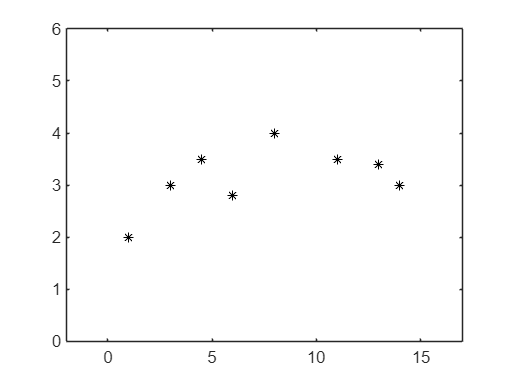

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];
plot(x,y,'k*')
axis([-2 17 0 6])

Linear spline

xx = 1: 0.1:14;
yy1 = interp1(x,y,xx,"linear")

yy1 =     2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0333    3.0667    3.1000    3.1333    3.1667    3.2000    3.2333    3.2667    3.3000    3.3333    3.3667    3.4000    3.4333    3.4667    3.5000    3.4533    3.4067    3.3600    3.3133    3.2667    3.2200    3.1733    3.1267    3.0800    3.0333    2.9867    2.9400    2.8933    2.8467


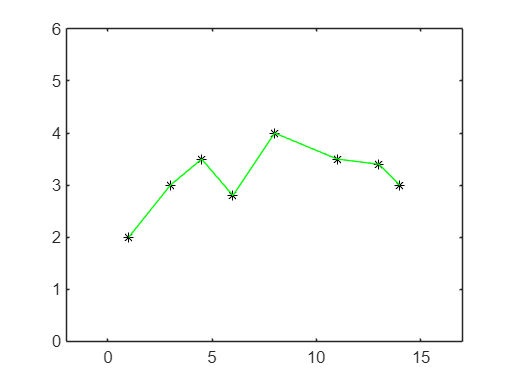



figure
plot(x,y,'k*')
hold on
plot(xx,yy1,'g-')
axis([-2 17 0 6])

Quadratic spline

xx = 1: 0.1:14;
%yy2 = quadspline(x,y,xx)


figure
plot(x,y,'k*')
hold on
plot(xx,yy1,'g-')
axis([-2 17 0 6])

Cubic spline (natural spline)

xx = 1: 0.1:14;
yy2 = natspline(x,y,xx)

yy2 =     2.0000    2.0463    2.0927    2.1392    2.1859    2.2328    2.2799    2.3274    2.3753    2.4236    2.4724    2.5218    2.5717    2.6224    2.6737    2.7259    2.7788    2.8326    2.8874    2.9432    3.0000    3.0578    3.1158    3.1732    3.2291    3.2826    3.3330    3.3793    3.4207    3.4563    3.4852    3.5066    3.5197    3.5235    3.5172    3.5000    3.4714    3.4327    3.3856    3.3319    3.2734    3.2117    3.1485    3.0857    3.0249    2.9679    2.9164    2.8721    2.8368    2.8122


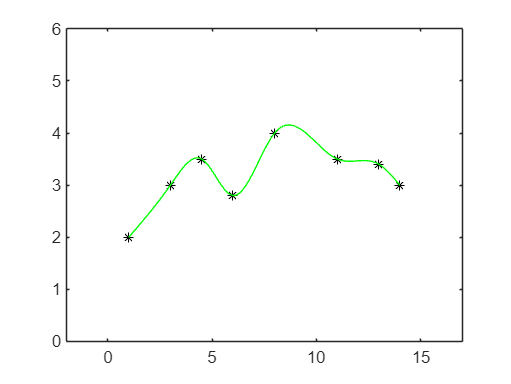



figure
plot(x,y,'k*')
hold on
plot(xx,yy2,'g-')
axis([-2 17 0 6])

Cubic spline (using interp1)

xx = 1: 0.1:14;
yy1 = interp1(x,y,xx,"spline")

yy1 =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111


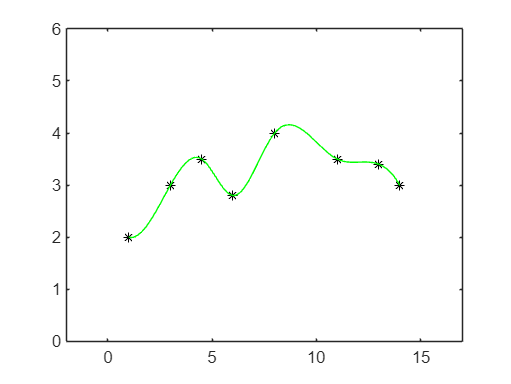



figure
plot(x,y,'k*')
hold on
plot(xx,yy1,'g-')
axis([-2 17 0 6])

Cubic spline (using spline)

xx = 1: 0.1:14;
yy1 = spline(x,y,xx)

yy1 =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111




figure
plot(x,y,'k*')
hold on
plot(xx,yy1,'g-')
axis([-2 17 0 6])

Cubic spline (using spline & ppval)

xx = 1: 0.1:14;

cs = spline(x,y)

cs = struct with fields:
      form: 'pp'
    breaks: [1 3 4.5000 6 8 11 13 14]
     coefs: [7×4 double]
    pieces: 7
     order: 4
       dim: 1


yy1 = ppval(cs,xx)

yy1 =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111



figure
plot(x,y,'k*')
hold on
plot(xx,yy1,'g-')
axis([-2 17 0 6])

Cubic spline (plot each segment with different colors)

xseg1 = linspace(x(1) ,x(2));
xseg2 = linspace(x(2) ,x(3));
xseg3 = linspace(x(3) ,x(4));
xseg4 = linspace(x(4) ,x(5));
xseg5 = linspace(x(5) ,x(6));
xseg6 = linspace(x(6) ,x(7));
xseg7 = linspace(x(7) ,x(8));

yseg1 = spline(x,y,xseg1)

yseg1 =     2.0000    1.9980    1.9965    1.9953    1.9945    1.9941    1.9941    1.9945    1.9953    1.9964    1.9980    1.9998    2.0021    2.0046    2.0076    2.0108    2.0144    2.0184    2.0227    2.0272    2.0322    2.0374    2.0429    2.0487    2.0549    2.0613    2.0680    2.0750    2.0823    2.0898    2.0976    2.1057    2.1140    2.1226    2.1315    2.1405    2.1499    2.1594    2.1692    2.1792    2.1894    2.1998    2.2105    2.2213    2.2324    2.2436    2.2550    2.2667    2.2784    2.2904


yseg2 = spline(x,y,xseg2)

yseg2 =     3.0000    3.0107    3.0213    3.0319    3.0424    3.0529    3.0633    3.0737    3.0840    3.0942    3.1044    3.1145    3.1246    3.1345    3.1444    3.1543    3.1640    3.1737    3.1833    3.1928    3.2022    3.2115    3.2208    3.2300    3.2390    3.2480    3.2569    3.2656    3.2743    3.2829    3.2913    3.2997    3.3079    3.3161    3.3241    3.3320    3.3398    3.3474    3.3550    3.3624    3.3697    3.3768    3.3839    3.3908    3.3975    3.4041    3.4106    3.4170    3.4232    3.4292


yseg3 = spline(x,y,xseg3)

yseg3 =     3.5000    3.4959    3.4915    3.4868    3.4819    3.4768    3.4715    3.4660    3.4602    3.4543    3.4481    3.4417    3.4352    3.4285    3.4216    3.4145    3.4073    3.3998    3.3923    3.3846    3.3767    3.3688    3.3606    3.3524    3.3440    3.3356    3.3270    3.3183    3.3095    3.3007    3.2917    3.2827    3.2736    3.2644    3.2552    3.2459    3.2365    3.2271    3.2177    3.2083    3.1988    3.1893    3.1797    3.1702    3.1607    3.1512    3.1416    3.1321    3.1226    3.1132


yseg4 = spline(x,y,xseg4)

yseg4 =     2.8000    2.7994    2.7994    2.7999    2.8009    2.8025    2.8046    2.8072    2.8103    2.8139    2.8180    2.8226    2.8277    2.8332    2.8391    2.8455    2.8523    2.8596    2.8672    2.8753    2.8838    2.8926    2.9018    2.9114    2.9213    2.9316    2.9422    2.9531    2.9644    2.9760    2.9878    3.0000    3.0124    3.0251    3.0381    3.0513    3.0648    3.0785    3.0924    3.1066    3.1210    3.1355    3.1503    3.1652    3.1803    3.1955    3.2109    3.2265    3.2421    3.2580


yseg5 = spline(x,y,xseg5)

yseg5 =     4.0000    4.0145    4.0283    4.0413    4.0535    4.0650    4.0758    4.0858    4.0951    4.1038    4.1117    4.1190    4.1257    4.1316    4.1370    4.1417    4.1458    4.1493    4.1522    4.1545    4.1563    4.1575    4.1582    4.1583    4.1579    4.1570    4.1556    4.1537    4.1514    4.1486    4.1453    4.1416    4.1375    4.1329    4.1280    4.1226    4.1169    4.1108    4.1044    4.0976    4.0904    4.0830    4.0752    4.0672    4.0588    4.0502    4.0413    4.0322    4.0228    4.0132


yseg6 = spline(x,y,xseg6)

yseg6 =     3.5000    3.4961    3.4924    3.4888    3.4854    3.4821    3.4790    3.4760    3.4732    3.4705    3.4679    3.4655    3.4632    3.4610    3.4590    3.4571    3.4552    3.4535    3.4519    3.4504    3.4491    3.4478    3.4466    3.4455    3.4445    3.4436    3.4428    3.4420    3.4413    3.4408    3.4402    3.4398    3.4394    3.4391    3.4388    3.4386    3.4385    3.4384    3.4383    3.4383    3.4383    3.4384    3.4385    3.4386    3.4388    3.4390    3.4392    3.4394    3.4397    3.4399


yseg7 = spline(x,y,xseg7)

yseg7 =     3.4000    3.3984    3.3968    3.3951    3.3934    3.3916    3.3898    3.3880    3.3861    3.3842    3.3823    3.3803    3.3782    3.3762    3.3741    3.3719    3.3697    3.3675    3.3652    3.3628    3.3605    3.3581    3.3556    3.3531    3.3505    3.3479    3.3453    3.3426    3.3398    3.3371    3.3342    3.3313    3.3284    3.3254    3.3224    3.3193    3.3162    3.3130    3.3097    3.3065    3.3031    3.2997    3.2963    3.2928    3.2892    3.2856    3.2820    3.2783    3.2745    3.2707


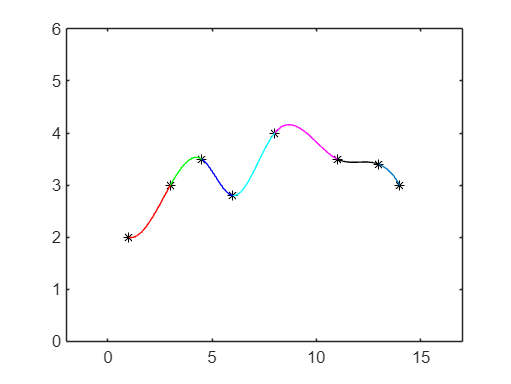


figure
plot(x,y,'k*')
hold on
plot(xseg1,yseg1,'r-')
plot(xseg2,yseg2,'g-')
plot(xseg3,yseg3,'b-')
plot(xseg4,yseg4,'c-')
plot(xseg5,yseg5,'m-')
plot(xseg6,yseg6,'k-')
plot(xseg7,yseg7,'-')
axis([-2 17 0 6])